## **Question 1**

- Consider the the Lorenz-63 model with the setting used in Project 1. The data assimilation problem is posed over the interval [0, T], starting with initial background states from N (x b 0 , B0). Observations are available at times ti = i ∆t, i = 0, . . . , N, tN = T. Use your synthetic observations, observation error covariance, and observation operator from Project 1.

**The code below is taken directly from my Project 1 implementation (modified to the L63 system)**

**1.1)**

- Implement the Lorenz-63 model (1) and solve it using a Matlab ode solver (ode45 or one integrator selected from MATLODE).

- Start with an initial condition where the states are drawn from a random distribution (e.g., x0 ∼N (0, 16)), then integrate for 5 time units. Save the result. This is our x[-1]true.

- Propagate for ∆t time units, and save. This is our reference state x[0]true.

- (You can use ∆t = 0.1.)

clear;
close all;
clc;

% Setting seed for reproducibility
rng(381996)

% Importing Lorenz96 model
m = otp.lorenz63.presets.Canonical;

% Model configurations
n_states = 3;
n_obs = 1000; % Number of observations
n_obs_states = 2;
x0 = normrnd(0,sqrt(16),[n_states,1]); % Inital condition of y0 drawn from N(0,16)
dt = 0.05; % time step unit

% Solving for for 5 time units (0.5) using inital conditions above
[~, x] = ode45(m.RHS.F, [0 dt*5], x0); % This is x[-1]true/reference state.
x_true_n1 = x(end,:).'; % Extracting states at final timestep

% Propogating for dt
[~, x] = ode45(m.RHS.F, [dt*5, dt*6], x_true_n1); % This is x[-1]true/reference state
x_true = x(end,:).'; % Extracting states at final timestep

**1.2)**

- Compute Nens normal random perturbations εbi ∼ N (0, σ2 INstate ) with σ = 0.2.

- Add to x[-1]true, and integrate the system starting from the perturbed initial conditions for ∆t time units.

- Save the resulting Nens states x. The members of this ensemble represent our set of background states Xb[0] .

n_ens = 1000;
sigma = 0.2;

% create ensemble members from perturbations of x_true
eps = normrnd(0,sigma,[n_states,n_ens]); % Perturbations (note normrnd(mu,sigma))
x_perturbed_n1 = x_true_n1 + eps;  % Adding to x_true[-1]

% init storage for ensemble (background state)
X_b_ens = zeros(n_states, n_ens);

% intergate system for one time unit for each ensemble member, store result
for i = 1:n_ens
    [~, x_ens] = ode45(m.RHS.F, [dt*5, dt*6], x_perturbed_n1(:, i));
    X_b_ens(:, i) = x_ens(end, :);
end

**1.3)**

- Using a large number of ensemble members compute the ensemble covariance Pb0.

- Check its condition number. If it is large build a modified background covariance that leads to a reasonably small condition number of the resulting covariance.

- This is our B0.

% A problem is called well-conditioned, if its condition number is small,
% i.e., in the order of 10, 100 or 1000
% and ill-conditioned if it is large: in the order of 10^6 - 10^10, and larger.
% https://cms.uni-konstanz.de/fileadmin/archive/informatik-saupe/fileadmin/informatik/ag-saupe/Webpages/lehre/na_08/Lab1/5_CondStab/html/CondStab.html

% Inbuilt covariance method
B0 = cov(X_b_ens.');
% Manual covariance check
X_ens_mean = mean(X_b_ens, 2);
X_delta = X_b_ens - X_ens_mean;
B0_manual = (1/(n_ens-1)).*(X_delta*X_delta.');

cond(B0), cond(B0_manual)

ans = 11.3549

ans = 11.3549

% Not needed as condition number is small
alpha = 0.001;
B0_downscale = (1-alpha)*B0 + alpha*eye(n_states);
cond(B0_downscale)

ans = 9.9081

% No need as already well conditioned
%B0 = B0_downscale

**1.4) **

- Obtain x0b by selecting one state with the smallest deviation from xtrue

[M,I] = min(sum(abs(X_b_ens - x_true(end,:).')));
x0b = X_b_ens(:, I);
x0b = x_true % TODO - update this

x0b =   -20.0487
  -16.0464
   47.1722


**1.5)**

- Run the reference trajectory starting from x_true[0] over the interval [0, T].

- Save the solution every ∆t time units.

- At each ti = i ∆t generate N_ens synthetic observations by adding to the reference solution H*xi normal random noise drawn from N (0, R), R = r^2 I N_obs, with r = 0.025.

T = 30;
time_steps = 0:dt:T;
x_start = x_true; % Storing inital x_true[0]

X_ref = zeros(n_states, length(time_steps));
X_ref(:, 1) = x_start;

% Run forward model and save results at each timestep
for t_id = 1:(length(time_steps)-1)
    [~, x] = ode45(m.RHS.F, [time_steps(t_id) time_steps(t_id)+dt], x_start);
    X_ref(:, t_id+1) = x(end,:);
    x_start = x(end,:).'; % For next iterations, use starting conditions based on prior state

end

% Apply observation operator and add random noise to reference trajectory
% Generating observation operator (observing every odd state)
A = eye(n_obs);
M = 1;
k = 1;
N = size(A);
H = reshape([reshape(A,M,[]);zeros(k,N(1)/M*N(2))],[],N(2)).';

% Redone such to only observe the first two states (For L63)
H = [1, 0, 0];

% Applying observation vector to reference trajectory
% H * Reference -> Observations, Clone Observatations + noise -> ensemble 
X_obvs = H * X_ref;
X_obvs_ens = repmat(X_obvs, 1,1, n_obs);

% Generating and applying observation noise (for each ensemble member)
obvs_sigma = 0.025;
R = obvs_sigma.^2 * eye(n_obs_states);
obvs_noise = normrnd(0,obvs_sigma,size(X_obvs_ens));  % (note normrnd(mu,sigma))
X_obvs_ens = X_obvs_ens + obvs_noise;

## **Question 2**

**2.1)**

- Consider the data assimilation problem posed over the interval [0, T], starting with initial background states from N (xb[0] , B0).

- Observations are available at times ti = i ∆t, i = 0, . . . , N, tN = T. Use your synthetic observations, observation error covariance, and observation operator from above.

% Unclear if these need to be resampled from this distribution or use the previously generated ensemble
n_particles = 1000;
X_ens_b = mvnrnd(x0b, B0, n_particles).'; 

**2.2)**

- Solve the data assimilation problem using the standard sequential importance with resampling (SIR) particle filter. 

- Resample when the effective number of particles decreases below a fraction of the total number, Neff ens ≤ α Nens, with 0 < α < 1 a tuning parameter under your control.

Run complete


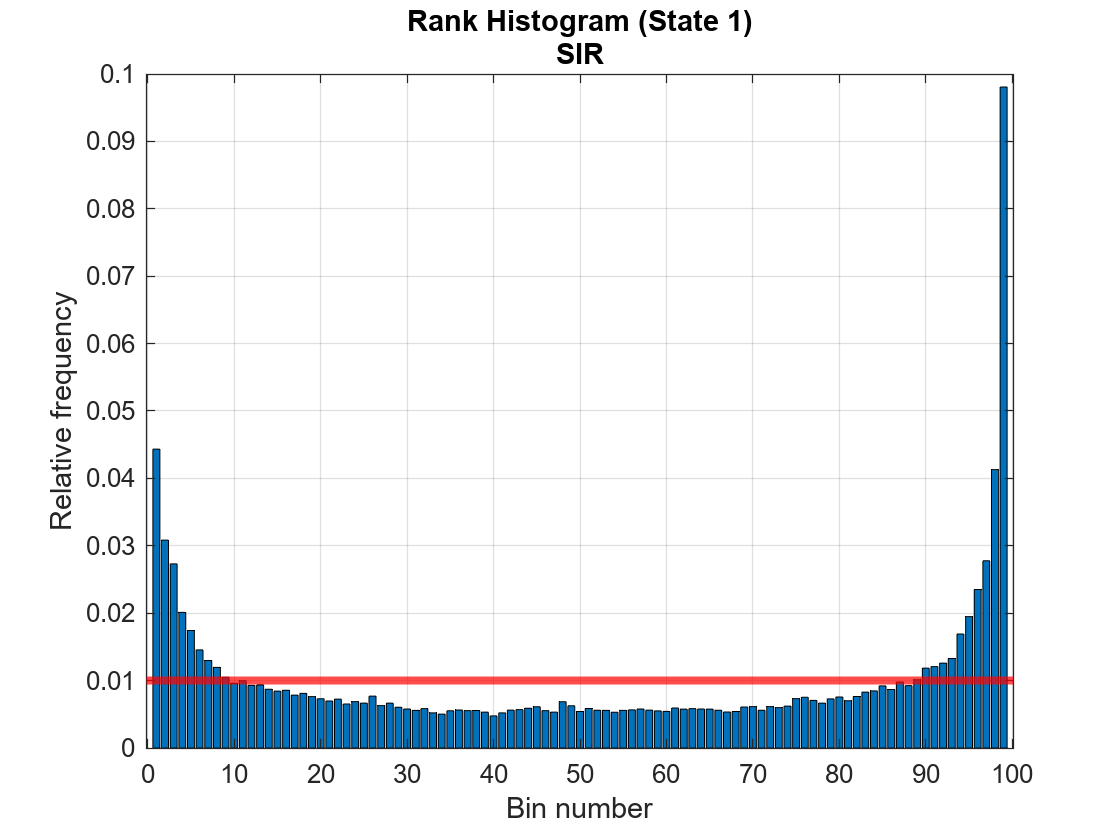

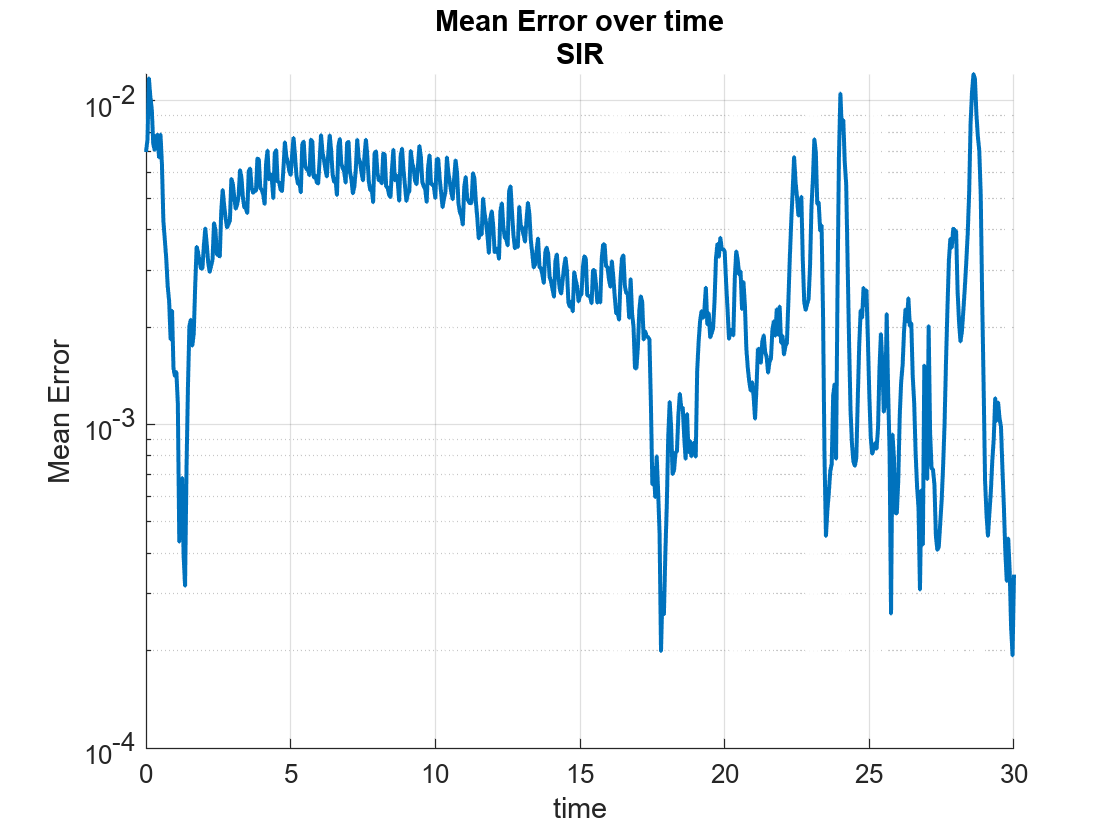

prediction = donald_SIR_63(m, X_ens_b, X_obvs_ens, X_ref, H, time_steps, n_states, n_particles, 1);

**2.3)**

Solve the data assimilation problem using a sequential importance sampling (SIS) approach, with two different proposal transition densities (your choice) selected out of the following list: 

- EnKF

EnKF run complete


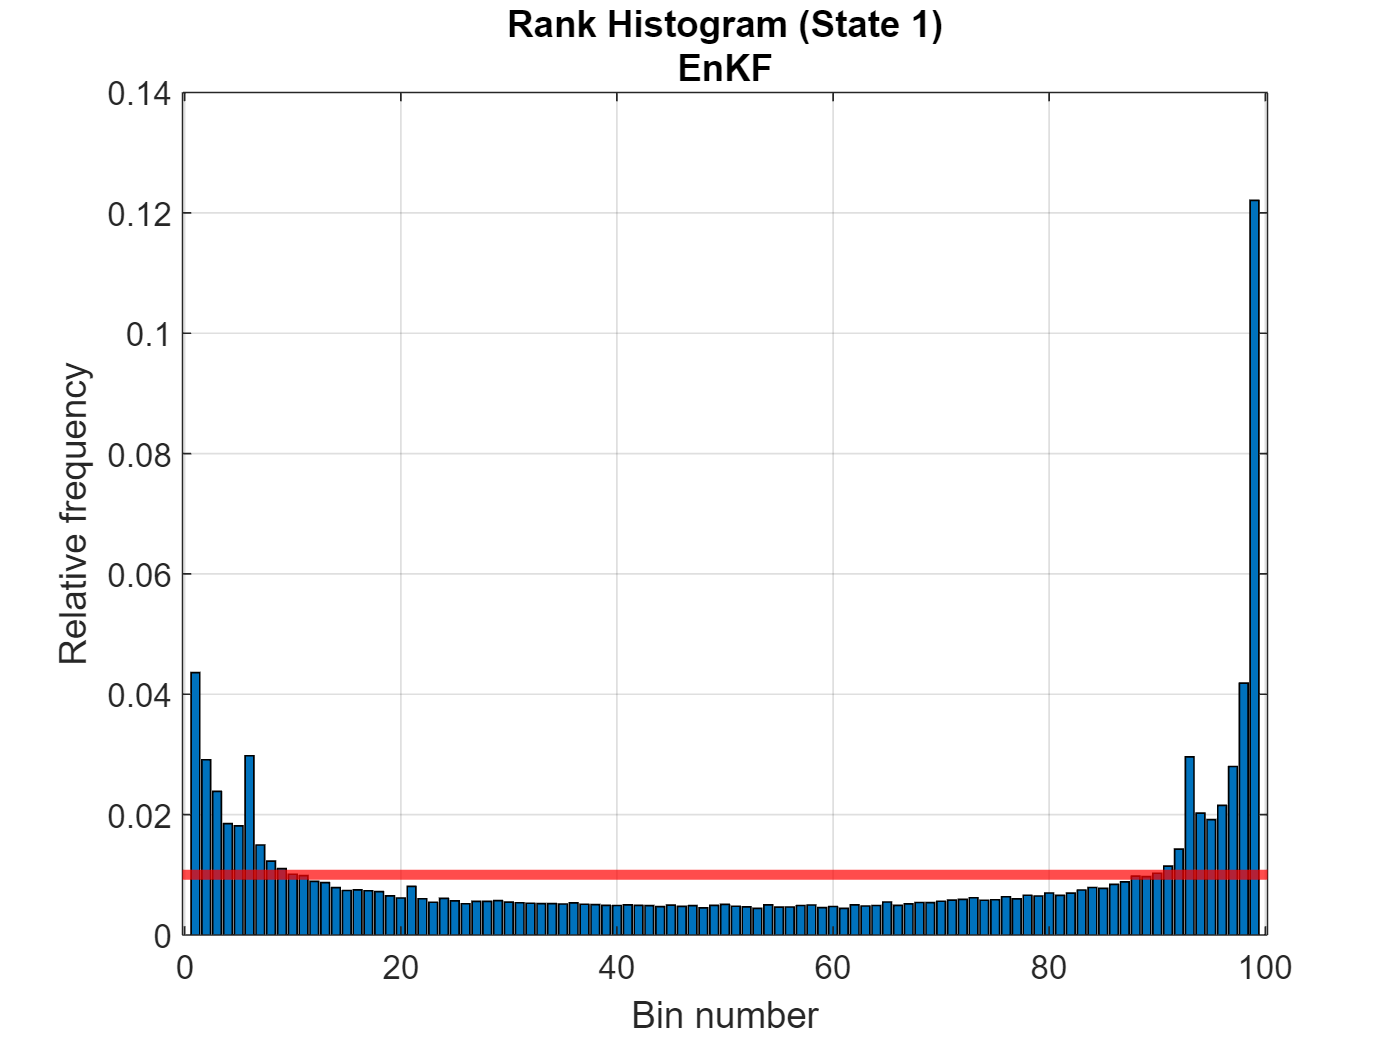

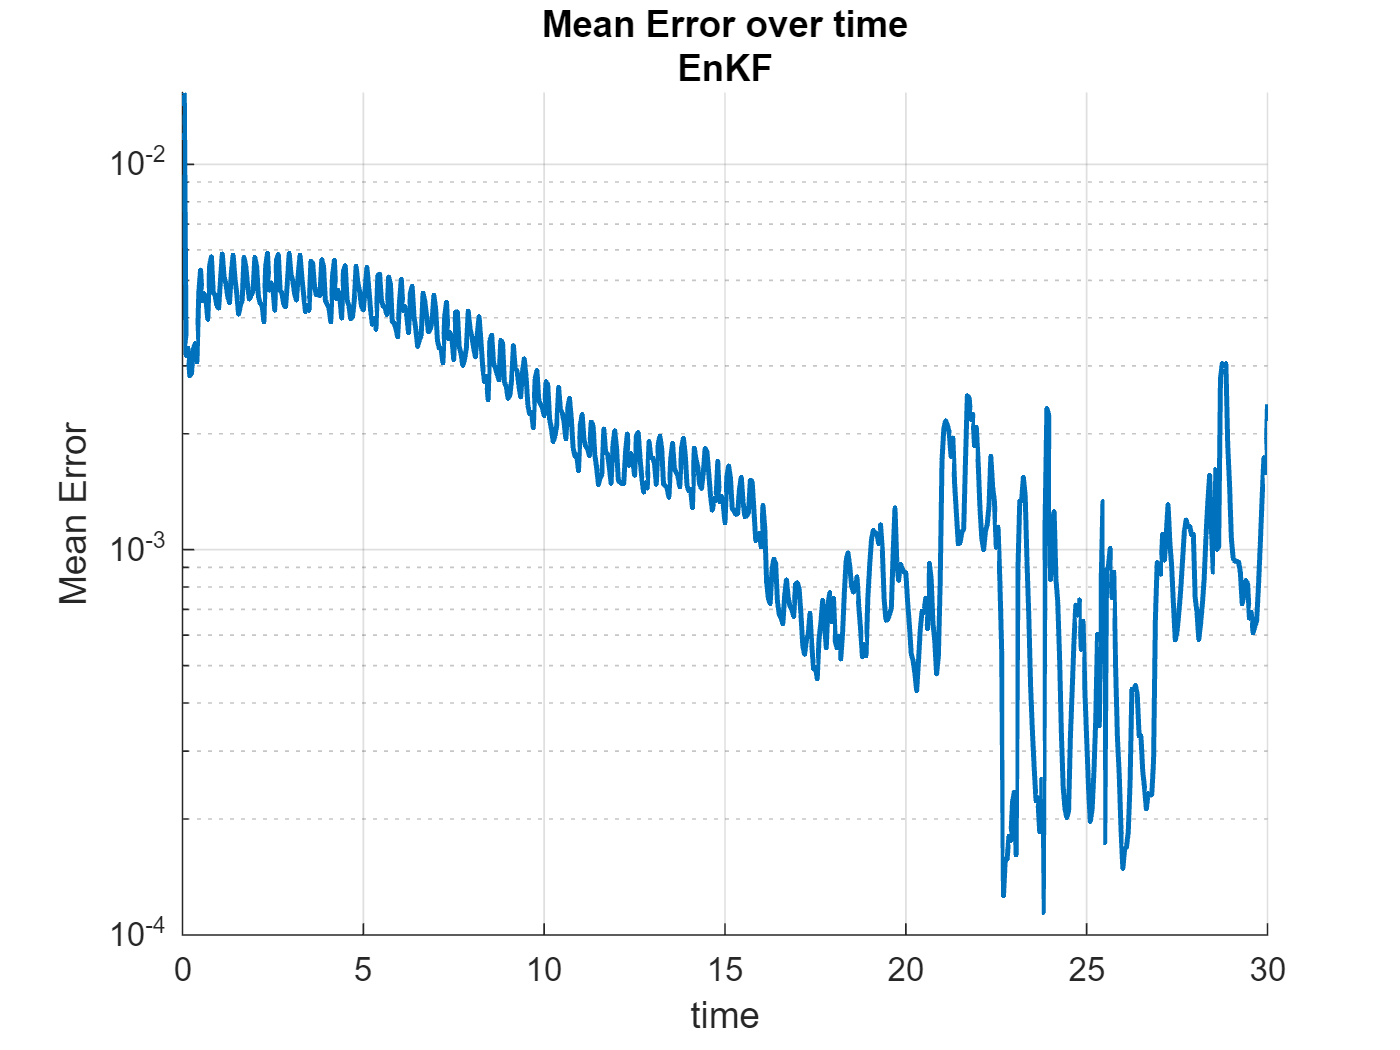

prediction = donald_ENKF_63(m, X_ens_b, X_obvs_ens, X_ref, H, time_steps, n_states, n_particles, 1);

- Nudging

Run complete


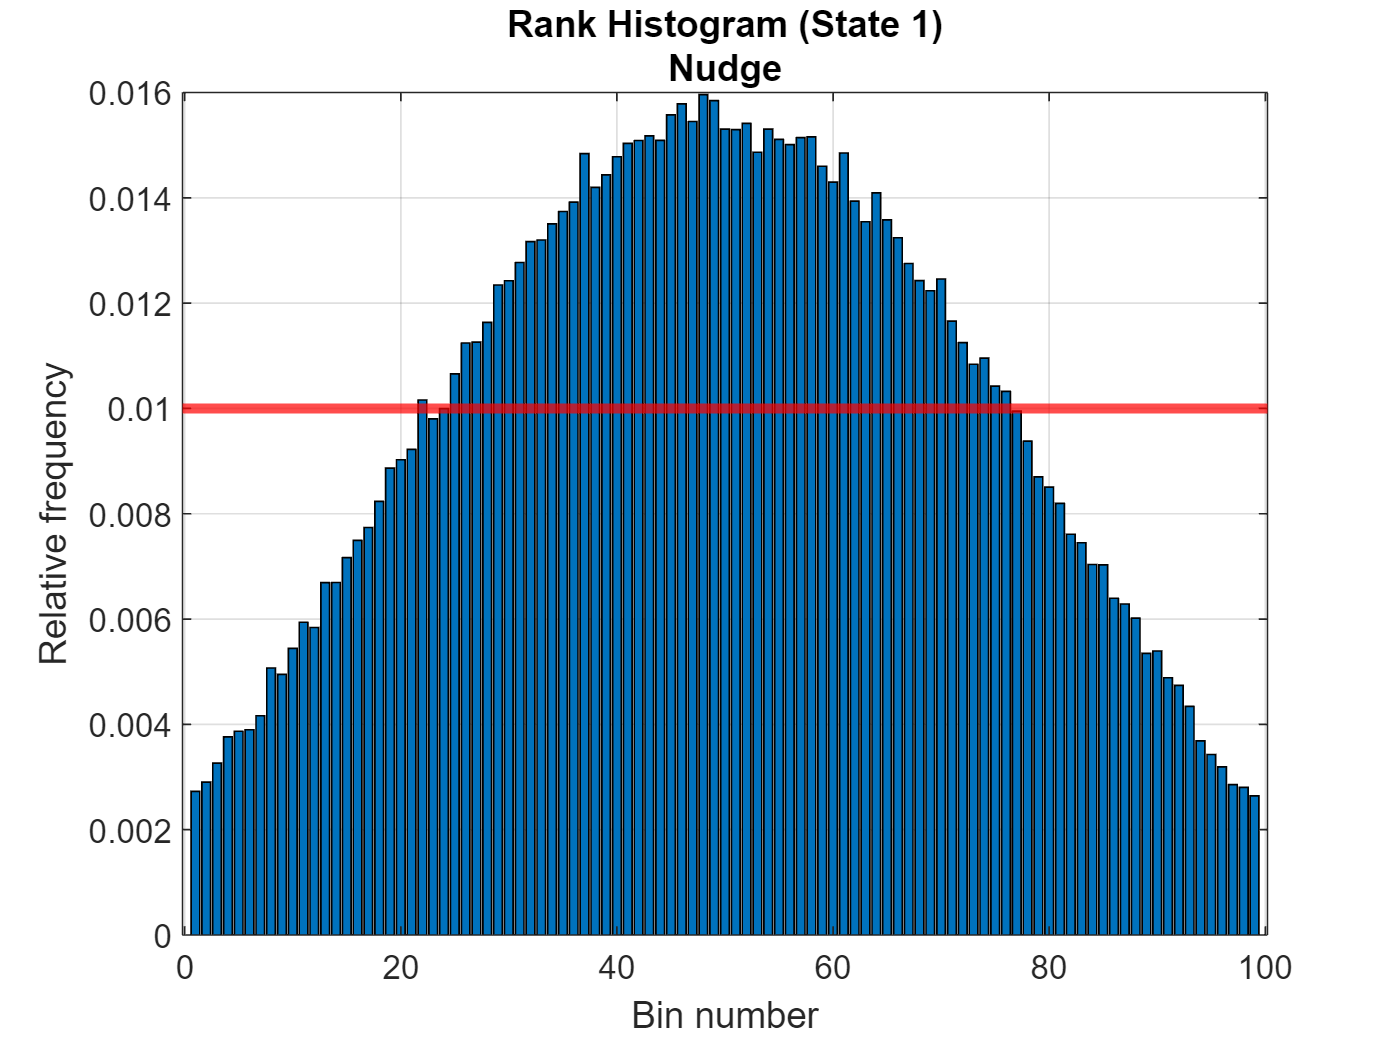

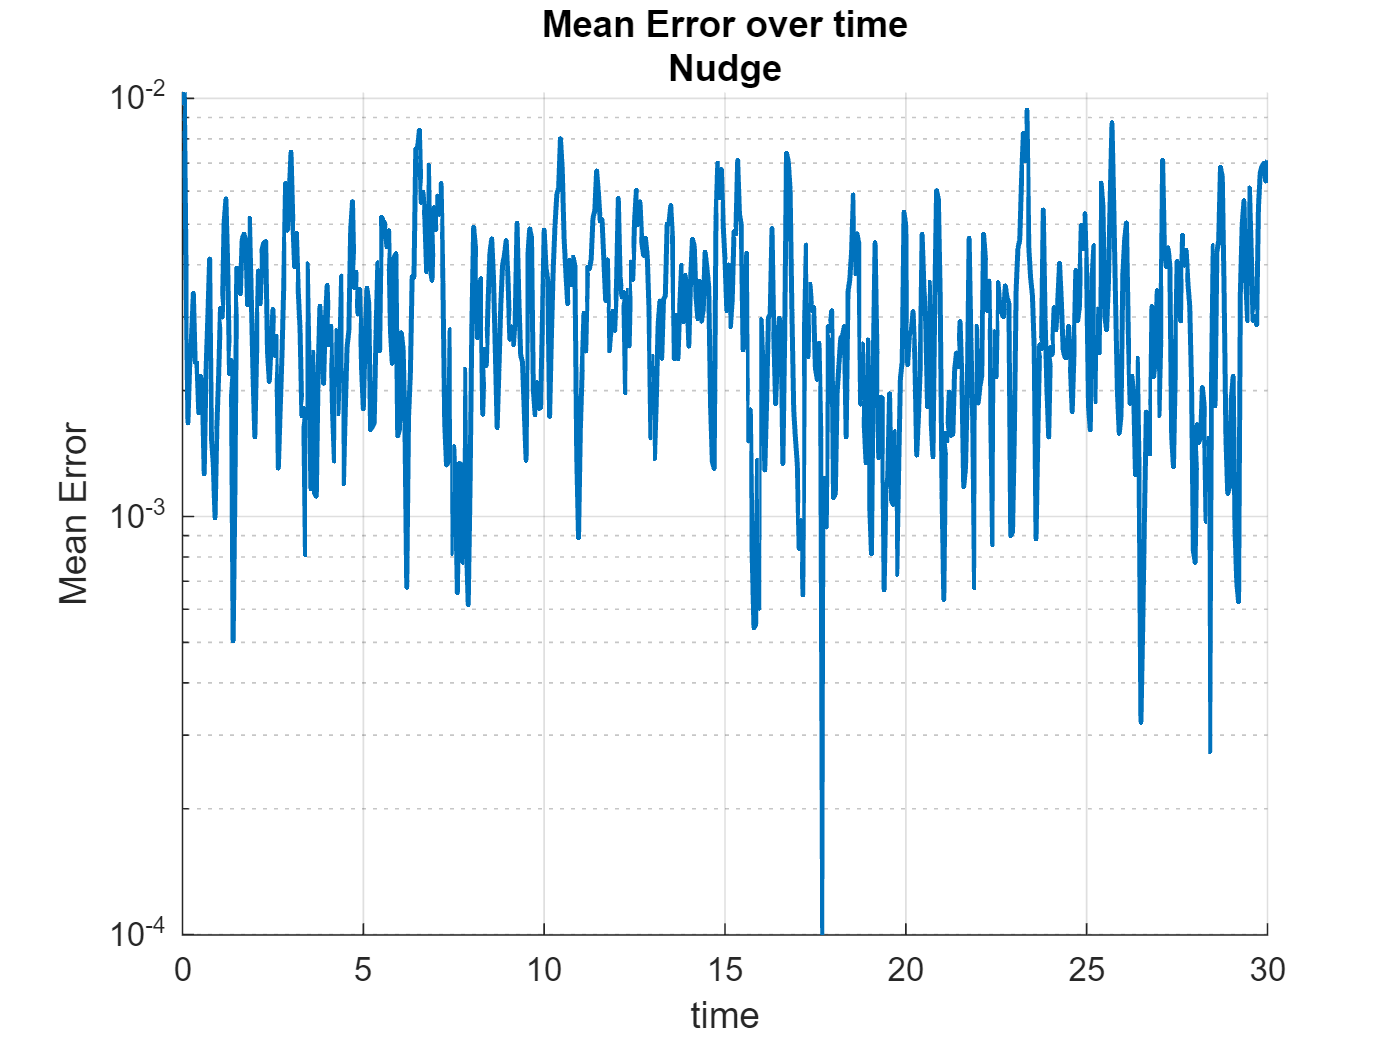

prediction = donald_nudge_63(m, X_ens_b, X_obvs_ens, X_ref, H, time_steps, n_states, n_particles, 1);